
% Gibbs sampling algorithm: 

% Given: 
% * random vector of variables X = (X1, ... XD)
% where each Xd is a random variable. 
% * current state: x_t = {x_1t, x_2t, ... x_Dt}

% (1) Initialize: {xi | i = 1... D}
% (2) Generate new state: 
% for t = 1... T
% --> sample x_1(t+1) ~ P(x1 | x_2t, x_3t, ... x_Dt)
% --> sample x_2(t+2) ~ P(x2 | x_1(t+1), x_3t, ... x_Dt)
% ...
% (3) Update the state: 
% x_(t+1) = {x_1(t+1), x_2(t+1), ..., x_D(t+1)}

% Prior parameters
mu0 = 0; 
sigma0 = sqrt(2);
a = 1; 
b = 1;


% Read the data: 
fileID = fopen('univarGauss.txt', 'r');
formatSpec = '%f'; 
% Sampled data N = 100 with  mean = 1.2, precision = 0.5
data = fscanf(fileID, formatSpec)

data =    0.902020000000000
   0.550360000000000
   1.692400000000000
   1.673100000000000
  -0.241470000000000
   5.193600000000000
   0.938550000000000
   0.488050000000000
  -0.129300000000000
   2.317800000000000
   1.096400000000000
   1.244300000000000
   3.581800000000000
   0.721490000000000
  -0.143970000000000
   0.371830000000000
  -0.592790000000000
  -1.227100000000000
   2.339300000000000
   2.985800000000000
   1.692400000000000
   3.829800000000000
  -1.028300000000000
  -0.700740000000000
   2.468700000000000
   3.947400000000000
   1.408300000000000
   1.441300000000000
   2.841700000000000
   1.878300000000000
   0.575770000000000
   0.320050000000000
   1.798900000000000
   0.462640000000000
  -0.802970000000000
   1.449300000000000
   1.911200000000000
   2.027100000000000
   3.051700000000000
   0.808760000000000
   1.964300000000000
  -0.263520000000000
   4.974400000000000
   1.882500000000000
   0.519270000000000
   0.436850000000000
   2.174900000000000
  -0.0

% Posterior distributions of mu and lambda are: 
% for mu: mu ~ Normal(muN, sigmaN^2)
% for lambda: lambda ~ Gamma(aN, bN), 


% note: need lambda args since muN, lambdaN are the
% parameters of the MU posterior

%muN = @(lambda, N, X) (mu0 + N * lambda * sigma0^2 * mean(X))/(1 + N * lambda * sigma0^2)
%lambdaN = @(lambda, N) sigma0^2 / (1 + N*lambda * sigma0^2)

% note: need mu arg since these are the parameters of 
% the LAMBDA posterior.
%aN = @(N) a + N/2
%bN = @(mu, X) b + (1/2) * sum(X - mu) .^ 2

% Defining the random number generators of the conditional
% posterior distributions of mu and lambda
%posteriorMu = @(lambda, N, X) normrnd(muN(lambda, N, X), sigmaN(lambda, N))
%posteriorLambda = @(mu,X) gamrnd(aN, bN(mu,X))

% Run algo for N = 0
N = 0

N =      0


X = 0

X =      0


[mus, lambdas] = gibbsAlgo(N, X);
mus'

ans =    1.150000000000000
  -2.557971296684453
   1.204042448105202
   1.723162768363242
   3.740651022716879
  -1.088382767861520
   0.064242550820741
   3.489834100140519
  -1.205034137742722
  -3.837177140297327
   1.053102257673105
  -2.377610757133464
  -1.485858601428695
  -0.238989584251889
   0.225945366132030
  -3.421494295003723
  -0.245830900149106
  -3.129733372665886
   0.976073811984725
   0.464502256847484
   5.252184875507448
   0.096013137060769
  -2.473017619131447
  -2.425858663205679
  -0.696440607755535
   1.852667463443475
  -0.455466785514539
   2.137971838727434
   2.896615618092642
   3.549456953898242
   1.561553051787284
  -0.474947699240910
   2.939609765386826
  -0.879362239181784
  -2.753925111796254
  -2.455219938629693
   1.702343928360425
   2.472350767700383
  -0.221395927427242
   0.412369457243176
  -1.041238100145162
  -5.740712524493293
  -0.902335980827002
   1.738365727838078
  -1.443077247277708
   1.784282040082947
  -1.701049550928091
  -1.28

lambdas'

ans =    0.700000000000000
   0.239100893632112
   0.086187137797417
   0.146657255950187
   0.060476591126960
   0.229760563393869
   0.294209380750763
   0.095658468109468
   0.662778354406497
   0.198844339103048
   0.960184189544431
   0.138869747394794
   0.896834408272604
   1.436081853353837
   0.735039686366682
   0.272031101102220
   0.242963035833789
   0.270849624958815
   0.753149371794791
   3.059587814096591
   0.066970151645749
   1.580696774395753
   0.031928060241824
   0.097779739798320
   2.989803347213585
   1.378921993910129
   0.448005261416916
   0.301175118926172
   0.052280042137233
   0.021175399161431
   1.029116059561425
   6.044083359339071
   0.085785462555282
   0.059734174223063
   0.010214713932448
   0.063879444915253
   0.682557059422226
   0.084866623635410
   0.137965110776553
   0.426711232537533
   0.987198686953280
   0.086930590109130
   0.193847103532821
   0.000853013271842
   0.817116031554032
   0.403311382656463
   2.495861836419534
   0.99

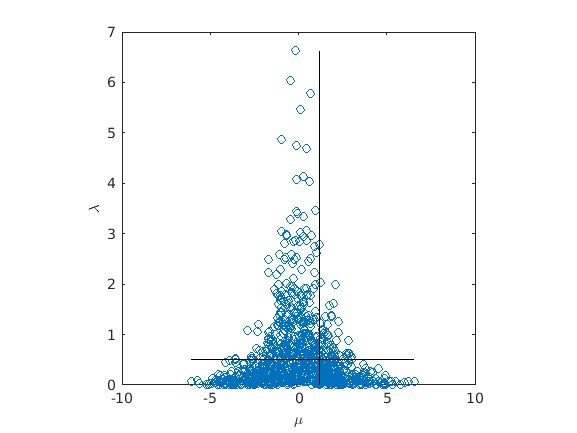


plotMuAndLambdas(mus, lambdas)

% Run algo for N = 10
N = 10; 
X = data(1:10, :);
[mus, lambdas] = gibbsAlgo(N, X);
mus'

ans =    1.150000000000000
   1.226828254684838
   1.538812087956460
   1.179497019656355
   1.143169595828549
   1.229494106123491
   0.855006790620621
   1.289047111955346
   1.595600137449861
   0.990517230739705
   1.121865675858080
   1.528975645070426
   1.223588973611141
   1.455841263992143
   0.611489066112606
   1.203733593032248
   1.081348854991367
   1.439104197548794
   1.360164053018171
   1.300124039640904
   1.555395543766616
   1.548219618025135
   0.700403648128186
   1.405130412877335
   1.099388669174807
   1.373567955093804
   1.421344490610039
   0.930090700533466
   1.000264429895882
   1.286372335921138
   0.958924991100083
   1.382691129240193
   0.959066412873871
   1.187619230145388
   1.589087239953125
   0.918711892711700
   1.270474680571469
   0.875862105229949
   0.891732339421553
   0.965691597165283
   1.302322954983929
   1.626984624439471
   1.319016062069529
   0.794656364360925
   1.374479107066365
   0.997488825936065
   1.328533792219458
   1.25

lambdas'

ans =    0.700000000000000
   0.308809519206887
   0.724131020592478
   0.460263949609366
   0.796716779159197
   0.323610033837731
   0.219928312487812
   0.274078048457949
   0.458302707255179
   0.361771102549185
   0.518020702818374
   0.512701409625006
   0.251961812304563
   0.272578164097245
   0.482639619629251
   0.574599254148007
   0.381701522669048
   0.429463048716268
   0.667753129992199
   0.378180827610685
   0.401919925056139
   0.279126583468483
   0.398427388436859
   0.256054251682798
   0.625784856492408
   1.045676080803266
   0.457765309324390
   0.208611137960377
   0.598934542057074
   0.634277755312150
   0.574513325010647
   0.397881333033564
   0.821688882609662
   0.344560397277247
   0.442854982743443
   0.705130736097698
   0.253357943828447
   0.236974792518503
   0.408475990866800
   0.315348645510758
   0.506574068212295
   0.362382672479820
   0.535946877719074
   0.422162002541501
   0.252941187641221
   0.370739238740037
   0.579526756058026
   0.32

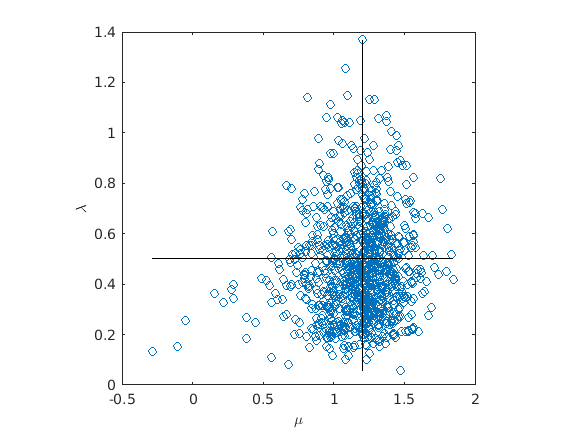


plotMuAndLambdas(mus, lambdas)

% Run algo for N = 100
N = 100; 
X = data;
[mus, lambdas] = gibbsAlgo(N, X);
mus'

ans =    1.150000000000000
   1.182585896864011
   1.177354573300098
   1.186296018258045
   1.183298528145009
   1.198725565312358
   1.190493059601386
   1.219628285004997
   1.192582676925174
   1.159983659517016
   1.183763581202515
   1.175510800124833
   1.192503851581524
   1.176310845017603
   1.191760372344762
   1.198835589495068
   1.169579425195180
   1.195560878066888
   1.197780351806657
   1.176362085792754
   1.189988649381042
   1.204442110746370
   1.218648684676072
   1.180380547414958
   1.210046633708101
   1.200125425167311
   1.179372613225032
   1.176418609856900
   1.196537136493047
   1.218560439307959
   1.213326127212387
   1.201512317341916
   1.213048441996023
   1.206786141318186
   1.167100110425322
   1.230864236567303
   1.188126042384919
   1.224649860259733
   1.199103037180718
   1.161029330982656
   1.216184932692981
   1.219072009488507
   1.180699892361117
   1.230044651597236
   1.188973145871411
   1.200723054303066
   1.188479541596142
   1.21

lambdas'

ans =    0.700000000000000
   0.562213368378512
   0.538772143650699
   0.563881148210748
   0.656664450744463
   0.523177256732056
   0.518991175578241
   0.508001324698197
   0.494889508179562
   0.502834096448899
   0.575321379270220
   0.661883062851244
   0.521624629745405
   0.515007031615165
   0.484060442641535
   0.586214625056987
   0.462728895633335
   0.542117140738406
   0.419072694251660
   0.419667456574934
   0.561741080186001
   0.437539018145832
   0.479559606596259
   0.577129517752918
   0.469120227706132
   0.530530314148776
   0.472558465979599
   0.680939906251570
   0.608432521539365
   0.520423619711276
   0.521531657052118
   0.714460851048677
   0.465160421203413
   0.546946351688886
   0.486208271648520
   0.536258608553769
   0.634910148164936
   0.534019563166710
   0.481798753705526
   0.590161067906733
   0.547891959280494
   0.449883970301519
   0.496137058414376
   0.498014779232668
   0.532266356198622
   0.415915003179458
   0.553670908743921
   0.54

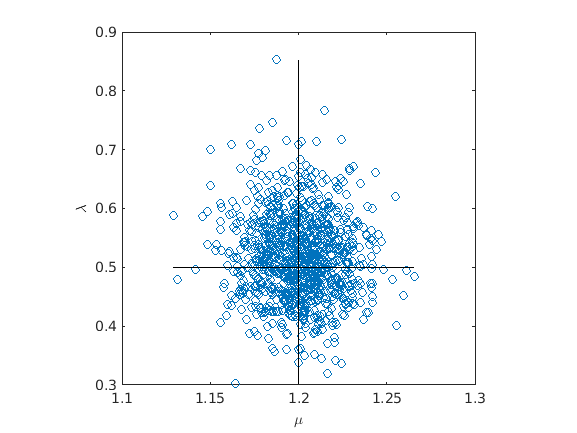


plotMuAndLambdas(mus, lambdas)


% At last, the sampled values of the mus and lambdas
% are near the center of mu = 1.2, lambdas = 0.5
% where these are the values of the multivariate
% joint pdf whose samples are in the data file. 

function plotMuAndLambdas(mus, lambdas)
    scatter(mus, lambdas); 
    axis square; 
    box on
    
    x0 = 1.2; 
    yMin = min(lambdas); 
    yMax = max(lambdas);
    y0 = 0.5; 
    xMin = min(mus); 
    xMax = max(mus);
    
    line([x0 x0], [yMin yMax], 'color', 'k');
    line([xMin xMax], [y0 y0], 'color', 'k');
    xlabel('\mu');
    ylabel('\lambda');
end

